function centerOfPressure = calculateCenterOfPressure(finShape, rootChord, tipChord, span, sweepAngle)
    switch lower(finShape)
        case 'aft-swept trapezoidal'
            % Trapezoidal center of pressure
            centerOfPressure = (rootChord + 2 * tipChord) / (3 * (rootChord + tipChord)) * span;
            
        case 'clipped-delta'
            % Clipped delta treated as a trapezoid with adjustment for higher sweep
            centerOfPressure = (rootChord + 2 * tipChord) / (3 * (rootChord + tipChord)) * span;
            
        case 'forward-swept trapezoidal'
            % Calculate center of pressure for a forward-swept trapezoidal fin
            centerOfPressure = (2 * rootChord + tipChord) / (3 * (rootChord + tipChord)) * span;

    end

    % Effective spanwise CoP, adjust for high sweep angles - worst case
    % assumption (sweepAngle > 0)
    if sweepAngle > 0
        centerOfPressure = centerOfPressure + (span * tand(sweepAngle) / 4);
    end
end


"The longitudinal stability characteristics are presented in figures 25(a) and 25(b) where the streamwise and spanwise wing centers of pressure on a single wing panel are presented for angles of attack of 5° and 50°, respectively. The data of figure 25(a) 10 show a variation in both the spanwise and streamwise center of pressure with changes in wing aspect ratio, whereas the data at an angle of attack of 50° (fig. 25(b)) collapse into a single curve. The variation in wing center of pressure can be directly related to the flow conditions about the wing. At low angles of attack, the lee-side flow characteristics for each wing vary considerably between attached and separated flow; however, as the wings are taken to a = 50°, the flow becomes quite similar and is characterized by two wing leading-edge vortices." [https://ntrs.nasa.gov/api/citations/19880008231/downloads/19880008231.pdf]

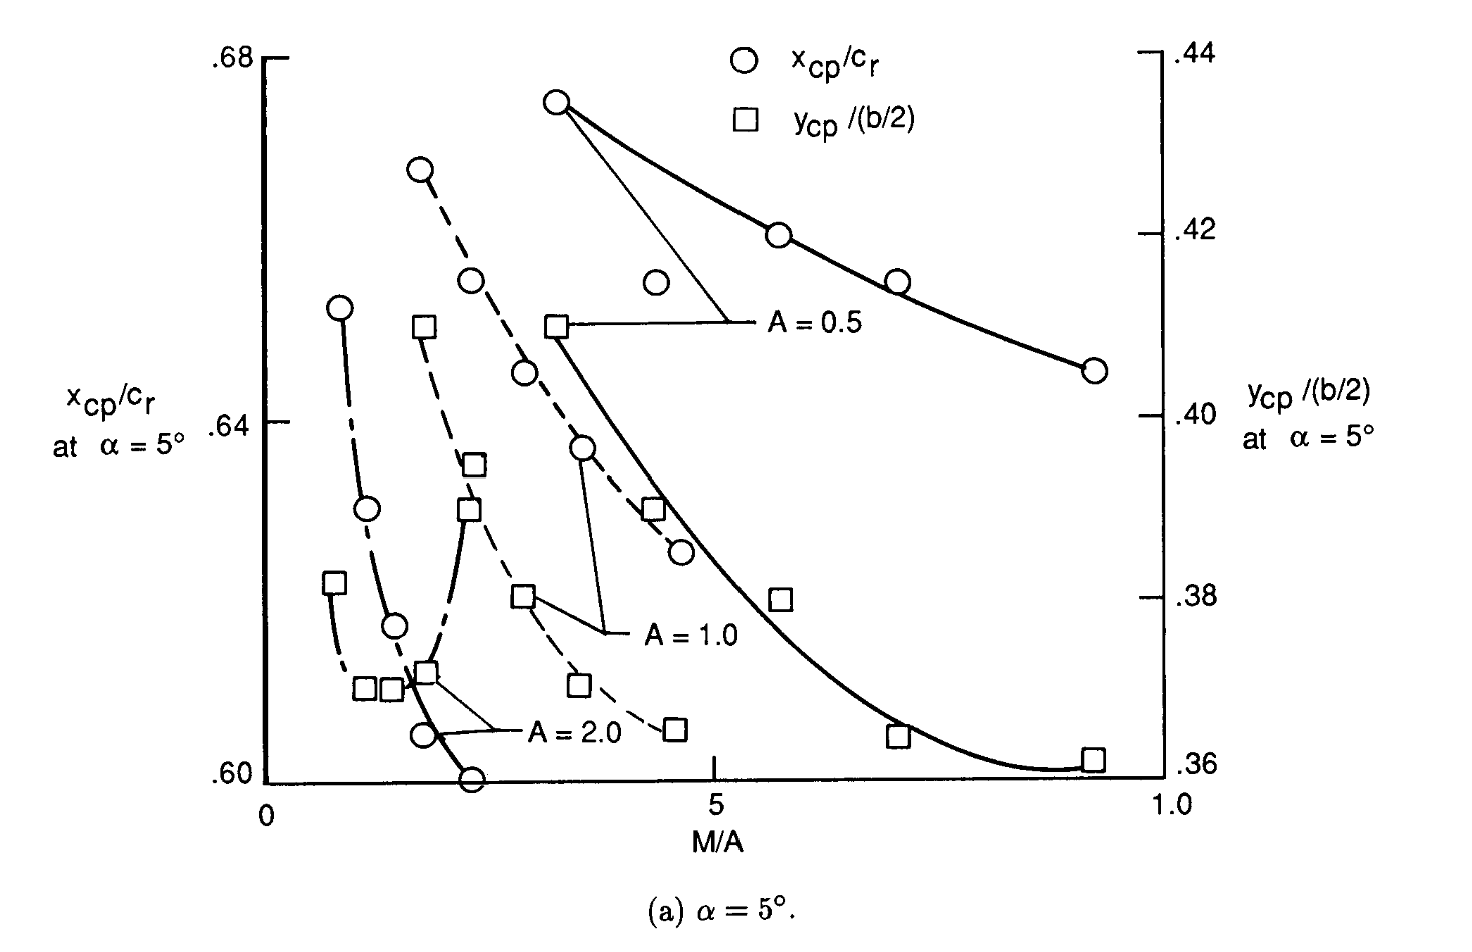   

M ... Mach Number

A ... Aspect Ratio

y_cp ... spanwise CoP

b ... span of full doubel delta wing

% Piqing Liu: 11.9.2 Effects of Mach Number on the Position of the Pressure

% https://ntrs.nasa.gov/api/citations/19800014762/downloads/19800014762.pdf

%CoP supersonic: http://aero-comlab.stanford.edu/aa200b/lect_notes/lect5.pdf